# Mapping Secchi Disk Depth with Lee et al. (2016)

% Set Up
clear
clc
close all 

% Change to virginiaCoast Folder
cd /Users/kellyluis/PycharmProjects/oceanoptics/Matlab/Examples/virginiaCoast/ % Change for your system

% Add Functions to Path 
addpath('/Users/kellyluis/PycharmProjects/oceanoptics/Matlab/Examples/virginiaCoast/functions') % Change for your system

cd('datasets/')
filename = 'L2017355154052.L2_LAC_OC';

% Read File into MA
L8 = readL2(filename);

% Specify Variables
wl = [443 482 561 655]; % Wavelengths
bbw = [0.002 0.0014 0.0008 0.004]; % Backscattering by Pure water
sa = 30; % Solar Zenith Angle

% Apply Secchi Algorithm to Entire L8 Image
for lat = 1:size(L8.Lat,1)
    for lon = 1:size(L8.Lat,2)
        
        % Format Rrs and Make Values < 0 NaN
        Rrs = [L8.rrs_443(lat,lon) L8.rrs_482(lat,lon) L8.rrs_561(lat,lon) L8.rrs_655(lat,lon)];
        
        Rrs(Rrs < 0) = nan;
        
        % QAA
        [a, bb, ~, ~, ~] = qaa_v6_l8(Rrs, wl);

        % Kd
        Kd =iop2kd(a,bb,bbw,sa);
        Kd(Kd<0) = nan;

        % Secchi
        [~, Secchi(lat,lon), ~] = secchi_L8(Rrs, Kd, wl);

    end
end



## Plot Secchi Map

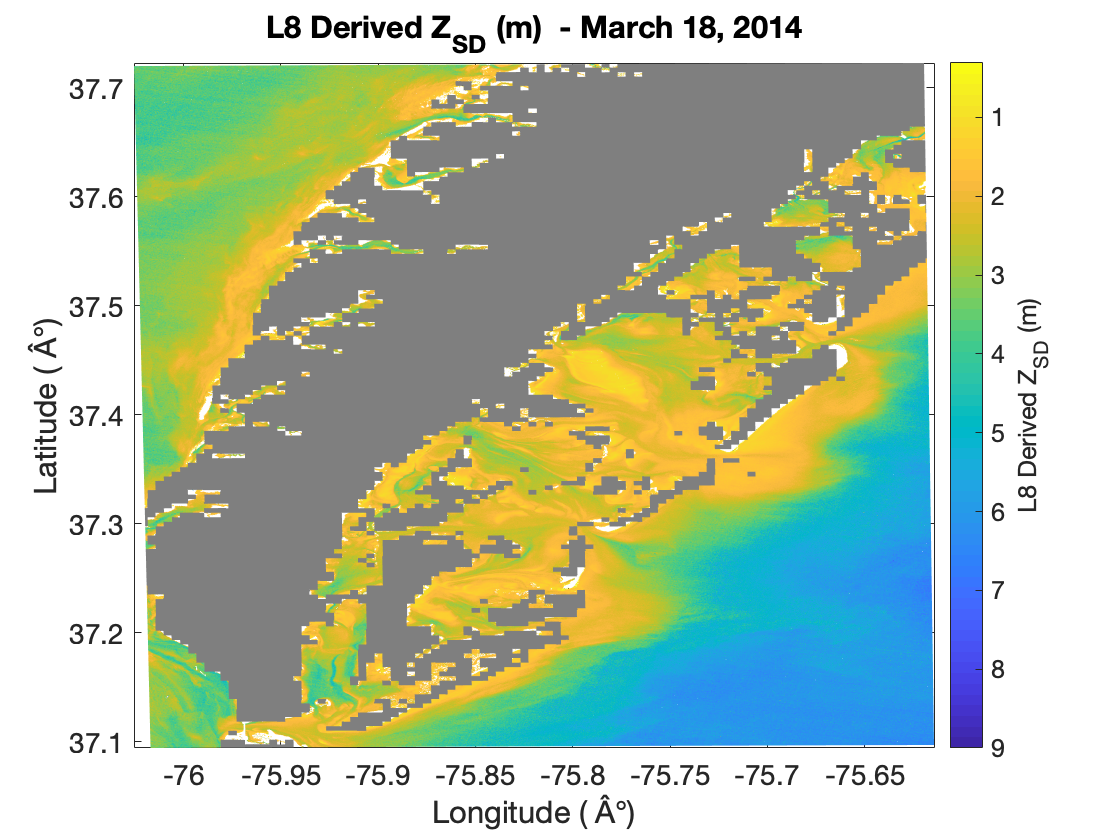

fig1 = figure(1);
sMasks = maskL2(Secchi,L8.l2_flags);
h = pcolor(L8.Lon,L8.Lat,reshape(sMasks,size(L8.Lon,1),size(L8.Lon,2))); shading flat; c = colorbar;
hold on
lMask(fig1,c);
ylabel('Latitude ( Â°)')
xlabel('Longitude ( Â°)')
title('L8 Derived Z_S_D Map')
set(gca,'FontSize',14)